a)  For the benefit of your customer, and for writing your report, you should understand the model in the web tool. Investigate and then describe this model, its properties, and what it predicts about pedestrian traffic by using the output the website provides, calling the website no more than 100 times (to save energetic costs and because we can imagine there may be licensing fees). In your answer, you should focus on how you use the online model output and your justification for this rather than simply stating an inferred model formulation. (4 marks)

- Microscopic models that are in the lecture notes that could apply to this - boids model, social forces model, 

- the pedestrian fundamental diagram is the relationship between crowd density and crowd flow

- slide set 3 seems most relevant

- width > 0, 0 < pedestrian density < 6 

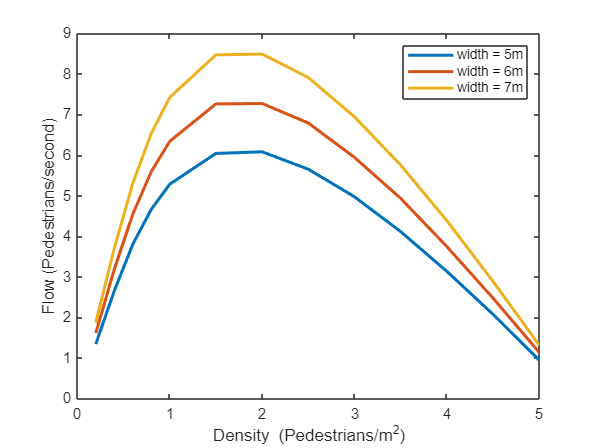

% Import the data as a table
dataTable = readtable('C:\Users\Izzy Popiolek\OneDrive - University of Bristol\Year 5\Transport and Mobility Modelling\coursework\q6\webtoolresults.csv','NumHeaderLines', 1);
% Convert the table to a matrix (if needed)
data = table2array(dataTable);

% plot crowd density vs crowd flow
plot(data(20:32,2), data(20:32,3), 'LineWidth', 2);
hold on
plot(data(33:45,2), data(33:45,3), 'LineWidth', 2);
hold on
plot(data(46:58,2), data(46:58,3), 'LineWidth', 2);
xlabel('Density (Pedestrians/m^2)');
ylabel('Flow (Pedestrians/second)');
% title('Web Tool - Fundamental Diagram');
legend('width = 5m', 'width = 6m', 'width = 7m');
hold off

%if isnan(x) || isnan(y) || y > 10 || x < 0.8. disp('Please enter valid numbers for both width and density.');
    
% Compute the flow value
x = 8; % width
y = 2; % density

z = round(100 * x * y * (1.34 * (1 - exp(-1.914 * ((1 / y) - (1 / 5.4))))) + RV(0, 0.75)) / 100;
extra_term = 1 - exp(4.321/x - 1/1.13)

extra_term = 0.2917


function [z0, z1] = BMT()
    % Generate random numbers
    u1 = rand();
    u2 = rand();
    
    % Box-Muller transform
    z0 = sqrt(-2.0 * log(u1)) * cos(2.0 * pi * u2);
    z1 = sqrt(-2.0 * log(u1)) * sin(2.0 * pi * u2);
end

function result = RV(mean, stddev)
    % Generate random value from normal distribution
    [z0, ~] = BMT();
    result = z0 * stddev + mean;
end

b) Usethemodelprovided in the web tool and the information provided in the question to make recommendations about the design of the bridge, focusing on elements relevant to foot traffic and considering the relevant stakeholders. You may suggest adapting the model, if necessary. Explain and justify your approach. (9 marks)

- what should the bridge width be?

- what is the max flow across the bridge? account also for a safety factor

- create a model of this in the microscopic python scripts we were given and match the flows to the web based tool

- Your customer is concerned with safety, construction costs, and user experience in this order of importance

- from graph given max flow is 5000 pedestrians over 5 minutes

- bridge must be safe but not excessively wide so as to increase the construction costs unnessecarily 

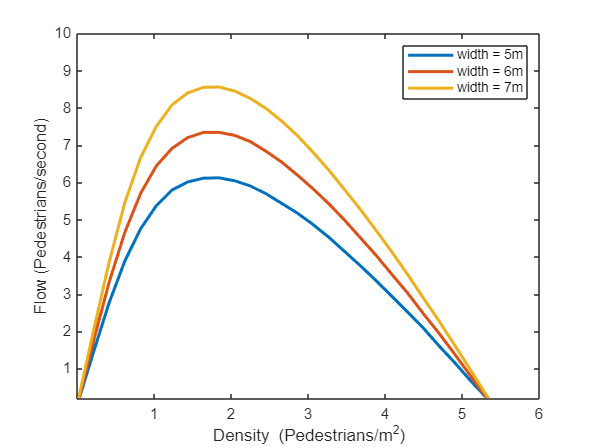

xvec = 8

        1000



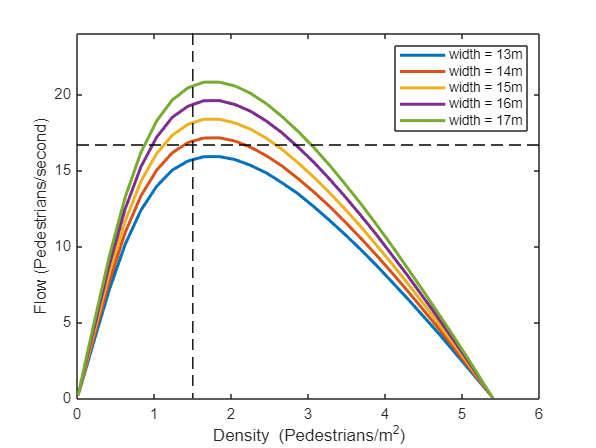

% using an analytical traffic flow model
% Parameters
x = 8; % Bridge width (meters)
y = 2; % Pedestrian density (people per square meter)
v0 = 1.5; % Maximum pedestrian speed (meters per second)
dc = 0.5; % Critical gap (meters). what is a good value to put in here for pedestrians
xvec = [5,6,7];
% yvec = [0.2, 0.4, 0.6, 0.8, 1, 1.5, 2, 2.5, 3, 3.5, 4, 4.5, 5];
yvec = linspace(0.01, 10, 50);
flow = zeros(length(xvec), length(yvec));
z = zeros(length(xvec), length(yvec));

for i =1:length(xvec)
    for j = 1:length(yvec)        
        % Compute equilibrium velocity
        da = 1 / yvec(j); % Gap between pedestrians
        %ve = (v0 / 2) * (tanh(da - dc) + tanh(dc)); % this is the same as the equation in question one
        % Compute flow
        % flow(i,j) = round(100 * (xvec(i) * yvec(j) * ve)) / 100;

        z(i,j) = round(100 * xvec(i) * yvec(j) * (1.34 * (1 - exp(-1.914 * ((1 / yvec(j)) - (1 / 5.4))))) + RV(0, 0.75)) / 100;
    end
end
% flow_per_width = flow ./ xvec';

figure;
% plot crowd density vs crowd flow
plot(yvec, z(1,:), 'LineWidth', 2);
hold on
plot(yvec, z(2,:), 'LineWidth', 2);
hold on
plot(yvec, z(3,:), 'LineWidth', 2);
ylim([0, 10]);
xlabel('Density (Pedestrians/m^2)');
ylabel('Flow (Pedestrians/second)');
% title('Web Tool Fundamental Diagram - ');
legend('width = 5m', 'width = 6m', 'width = 7m');
hold off